Significant beta spectrum - same color bar

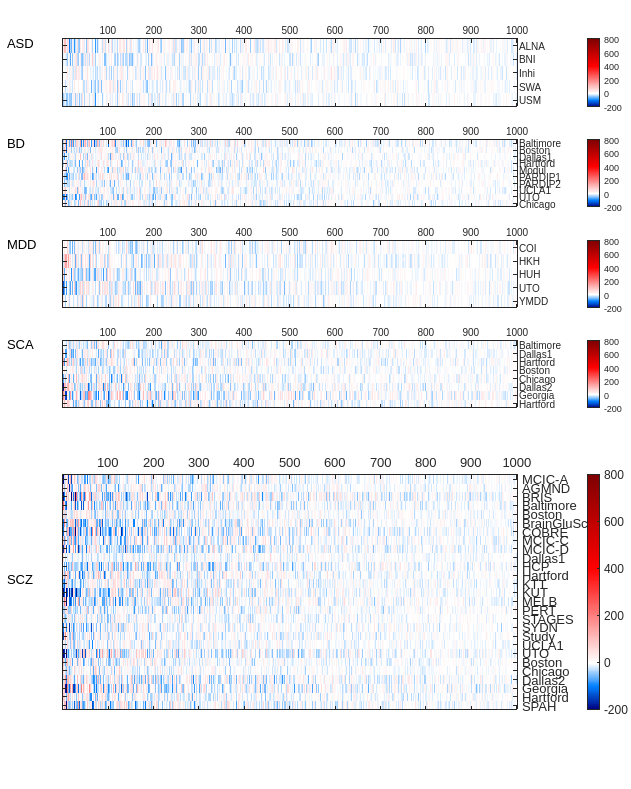

clear all
close all

diagnosis = {'HC', 'BD', 'SCA',...
    'SCZ', 'ASD', 'MDD' };
plotOrder = [5, 2, 6, 3, 4]; %to match with plot in vbm
nDiag = length(diagnosis); 

load('corr_MBM.mat');

nSite = length(map.numericFolders);

fig = figure('Position', [200 200 2000 2500]);
set(fig,'color','w');
factor_x = 1.2;
factor_y = 1.5;
init_x = 0.1;
init_y = 0.1;
num_row = 7;
num_col = 1;
length_x = (0.82 - init_x)/(factor_x*(num_col-1) + 1);
length_y = (0.95 - init_y)/(factor_y*(num_row-1) + 1);
lineWidth = 2;

font_name = 'Arial';
font_size = 10;
fontsize_legend = 8;

for iDiag = 1:nDiag-1
    
[isDiag locDiag] = ismember(map.diag,num2str(plotOrder(iDiag)));
siteString = (map.site(isDiag));
[siteString] = change_siteName(siteString);
nSite = length(siteString);

if iDiag == 5
    ax1 = axes('Position', [init_x, init_y length_x length_y*3.5]);
    a32 = annotation(fig, 'textbox', [0, ax1.Position(2)+length_y*2, 1, 0.01], 'string', char(diagnosis(plotOrder(iDiag))), 'edgecolor', 'none', ...
    'FontName',font_name,'FontSize',font_size, 'horizontalalignment', 'left');
else
ax1 = axes('Position', [init_x, init_y+length_y*factor_y*(num_row-iDiag) length_x length_y]);
a32 = annotation(fig, 'textbox', [0, ax1.Position(2)+length_y, 1, 0.01], 'string', char(diagnosis(plotOrder(iDiag))), 'edgecolor', 'none', ...
    'FontName',font_name,'FontSize',font_size, 'horizontalalignment', 'left');
end

hm = imagesc(map.beta(isDiag,:));
clim([-200 800]);
colormap(ax1, bluewhitered(ax1));
colorbar('Position', [0.93, ax1.Position(2), 0.02, ax1.Position(4)])
set(ax1,'xaxisLocation','top','yaxisLocation','right');
yticks(ax1,[1:nSite])
yticklabels(ax1,siteString(1:end))
% set(ax1,'box','off')
% grid off
% xlim([0.5,nSite+0.5])
% ylim([0.5,nSite+0.5])

end